# Compare solar panel enrgy production to theory

## Theoretical power production 

Define latitude of the solar panels and declination of the sun

lat= 42 +17/60

lat = 42.2833

dec= 23.45

dec = 23.4500

Convert from degrees to radians

lat=lat*pi/180

lat = 0.7380

dec=deg2rad(dec)

dec = 0.4093

Make a vector of times from 5:30 am to 8pm (slighhtly after sunrise to slighthly before sunset). Use 15-minute (1/4-hour) increments, to match mesured data.

t= 5.5:0.25:20

t =     5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500   12.5000   12.7500   13.0000   13.2500   13.5000   13.7500   14.0000   14.2500   14.5000   14.7500   15.0000   15.2500   15.5000   15.7500   16.0000   16.2500   16.5000   16.7500   17.0000   17.2500   17.5000   17.7500



LST=t-1+14.6/60

LST =     4.7433    4.9933    5.2433    5.4933    5.7433    5.9933    6.2433    6.4933    6.7433    6.9933    7.2433    7.4933    7.7433    7.9933    8.2433    8.4933    8.7433    8.9933    9.2433    9.4933    9.7433    9.9933   10.2433   10.4933   10.7433   10.9933   11.2433   11.4933   11.7433   11.9933   12.2433   12.4933   12.7433   12.9933   13.2433   13.4933   13.7433   13.9933   14.2433   14.4933   14.7433   14.9933   15.2433   15.4933   15.7433   15.9933   16.2433   16.4933   16.7433   16.9933


sunangle=sin(dec)*sin(lat)+cos(dec)*cos(lat)*cosd(15*(LST-12));
plot(t,sunangle,'y');

xlabel('time of day')
ylabel('Energy production (kW)')
subplot(2,1,1)
grid on

s_inc=1.4883*0.7.^(sunangle.^-0.678);


Calculate the final theorectical production for the entire solar panel array 

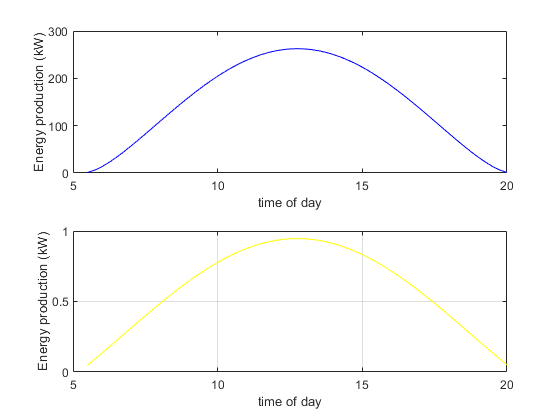

production_theory=270*s_inc.*sunangle;
plot(t,production_theory,'b');

xlabel('time of day')
ylabel('Energy production (kW)')

subplot(2,1,2)
grid on